# Gaze-biases

## Housekeeping

### Load Data

The mat file loaded in, below, contains the tables rquired to assess gaze biases. Note that the data has been truncated to account for terminal NDT (see text for details)

- gazeBias: data from standard sessions

- soa: data from gaze-manipulation sessions

clear; close all; clc
load GazeBiases.mat
rng(56,'twister') % random seed for replicability

### Variable Definitions

The following variables are present in both tables:

- firstFixIsLeft: logical indicator as to whether the first fixation was to left (true) or right (false) target 

- chosen: which target was chosen (1 = left, 0 = right)

- vDiff: left value - right value

- session: session identifier

- monk: monkey identifier

The following variables are only present in the *gazeBias *table:

- timeAdv: time advantage for the left item, computed as (total dwell time left - total dwell time right)

- totFix: total number of fixations in the trial

- lastFixlastFixlastFixIsLeftefteft: logical indicator as to whether the final fixation was to left (true) or right (false) target 

- correctProb: probability of choosing the left item after correcting for value (see text for details)

% for the cumulative gaze-time bias and the final fixation bias, analyses
% do not include trials with only a single fixation. Here we create an
% index of single fixation trials
sing = gazeBias.totFix == 1; 

The following variable is only present in the soa table:

- condition: logical indicator denoting whether the stimulus onset was staggered (true) or the targets appeared simultaneously (false)

## Initial Fixation Bias

### Analysis

#### Standard Sessions

% initial fixation bias: mixed effects model
firstFix = fitglme(gazeBias,'chosen ~ vDiff + firstFixIsLeft +(vDiff + firstFixIsLeft|monk)','Distribution','Binomial')

firstFix = Generalized linear mixed-effects model fit by PL

Model information:
    Number of observations           30351
    Fixed effects coefficients           3
    Random effects coefficients          6
    Covariance parameters                6
    Distribution                    Binomial
    Link                            Logit 
    FitMethod                       MPL   

Formula:
    chosen ~ 1 + vDiff + firstFixIsLeft + (1 + vDiff + firstFixIsLeft | monk)

Model fit statistics:
    AIC           BIC           LogLikelihood    Deviance  
    1.6608e+05    1.6615e+05    -83029           1.6606e+05

Fixed effects coefficients (95% CIs):
    Name                        Estimate    SE          tStat     DF       pValue        Lower       Upper   
    {'(Intercept)'     }        -0.34495    0.033919    -10.17    30348    2.9581e-24    -0.41143    -0.27846
    {'vDiff'           }          1.3844  

% ratio of the firstFixIsLeft coefficient to the vDiff coefficient. Taken as a metric of the change in subjective value attributable to the direction of the first fixation 
double(firstFix.Coefficients(3,2))/double(firstFix.Coefficients(2,2))

ans = 0.4654

% 

% run anova on the output of the model
firstFixAnova = anova(firstFix)

firstFixAnova =     ANOVA marginal tests: DFMethod = 'residual'

    Term                      FStat     DF1    DF2      pValue    
    {'(Intercept)'   }        103.42    1      30348    2.9581e-24
    {'vDiff'         }          5643    1      30348             0
    {'firstFixIsLeft'}        12.813    1      30348     0.0003448


#### Gaze-Manipulation Sessions

% gaze-manipulation aka, stimulus onset asynchrony (soa): 
% mixed effects model
soaModel = fitglme(soa,'chosen~ vDiff + firstFixIsLeft*condition + (1 + vDiff + firstFixIsLeft*condition|monk)','Distribution',"Binomial")

soaModel = Generalized linear mixed-effects model fit by PL

Model information:
    Number of observations           12833
    Fixed effects coefficients           5
    Random effects coefficients         10
    Covariance parameters               15
    Distribution                    Binomial
    Link                            Logit 
    FitMethod                       MPL   

Formula:
    chosen ~ 1 + vDiff + firstFixIsLeft*condition + (1 + vDiff + firstFixIsLeft*condition | monk)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    66599    66748    -33280           66559   

Fixed effects coefficients (95% CIs):
    Name                                    Estimate     SE         tStat       DF       pValue         Lower       Upper   
    {'(Intercept)'                 }          -0.2157    0.13177     -1.6369    12828        0.10167    -0.47398    0.042588
    {'firstFixIs

% ratio of the firstFixIsLeft coefficient to the vDiff coefficient. Taken as a metric of the change in subjective value attributable to the direction of the first fixation 
double(soaModel.Coefficients(2,2))/double(soaModel.Coefficients(3,2))

ans = 0.5469

%run anova on the output of the model
soaAnova= anova(soaModel)

soaAnova =     ANOVA marginal tests: DFMethod = 'residual'

    Term                                FStat      DF1    DF2      pValue     
    {'(Intercept)'             }         2.6796    1      12828        0.10167
    {'firstFixIsLeft'          }         28.509    1      12828     9.4832e-08
    {'vDiff'                   }         988.35    1      12828    4.6678e-209
    {'condition'               }         0.3118    1      12828        0.57659
    {'firstFixIsLeft:condition'}        0.48323    1      12828        0.48697


### Plot Results

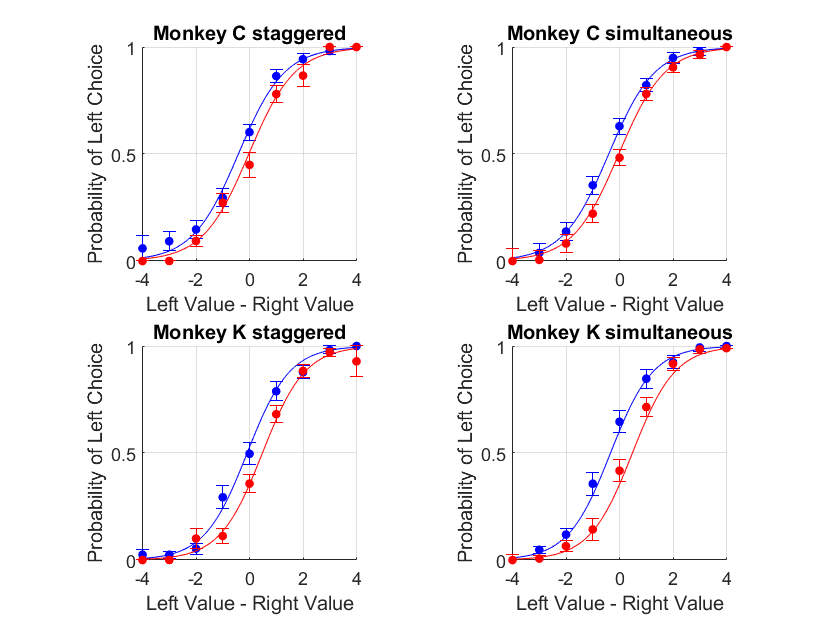

% get session-wise metrics
monks = {'MonkeyC','MonkeyK'};
xChoice = linspace(-4,4,81)';
idx =[1:81; 82:162];
idx2 = [1:41; 42:82];


soaChoice = grpstats(soa,{'session','condition','vDiff','monk','firstFixIsLeft'},{'mean'},...
    'DataVars','chosen');

soaChoice2 = grpstats(soaChoice,{'condition','vDiff','monk','firstFixIsLeft'},{'mean','sem'},...
    'DataVars',{'mean_chosen'});
x = repmat([-4:0.1:4]',[2 1]);
xPredSOA_left = soa(find(soa.condition == 1,162,"first"),:);
xPredSOA_left.vDiff = x;
xPredSOA_left.firstFixIsLeft = logical(ones(162,1));
xPredSOA_left.monk(82:end) = "MonkeyK";
xPredSOA_right = soa(1:162,:);
xPredSOA_right.vDiff = x;
xPredSOA_right.monk(82:end) = "MonkeyK";
xPredSOA_right.firstFixIsLeft = logical(zeros(162,1));
SOAYhat_left = predict(soaModel,xPredSOA_left);
SOAYhat_right = predict(soaModel,xPredSOA_right);

xPredNonSOA_left = soa(find(~soa.condition,162,"first"),:);
xPredNonSOA_left.vDiff = x;
xPredNonSOA_left.firstFixIsLeft = logical(ones(162,1));
xPredNonSOA_left.monk(82:end) = "MonkeyK";
xPredNonSOA_right = soa(1:162,:);
xPredNonSOA_right.vDiff = x;
xPredNonSOA_right.monk(82:end) = "MonkeyK";
xPredNonSOA_right.firstFixIsLeft = logical(zeros(162,1));
nonSOAYhat_left = predict(soaModel,xPredNonSOA_left);
nonSOAYhat_right = predict(soaModel,xPredNonSOA_right);



%% plot initial fixation bias SOA
monkeys = {'Monkey C','Monkey K'};
for monk = 1:2
    % soa curve
    subplot(2,2,monk*2-1)
    errorbar(-4:4,soaChoice2(soaChoice2.monk == monks{monk} & soaChoice2.condition & soaChoice2.firstFixIsLeft,:).mean_mean_chosen, ...
        soaChoice2(soaChoice2.monk == monks{monk} & soaChoice2.condition & soaChoice2.firstFixIsLeft,:).sem_mean_chosen,'Color','b',...
        'LineStyle','None','Marker',".","MarkerSize",15); hold on
    plot(xChoice,SOAYhat_left(idx(monk,:)),'color','b')
    
    errorbar(-4:4,soaChoice2(soaChoice2.monk == monks{monk} & logical(soaChoice2.condition) & soaChoice2.firstFixIsLeft == 0,:).mean_mean_chosen, ...
        soaChoice2(soaChoice2.monk == monks{monk} & soaChoice2.condition & soaChoice2.firstFixIsLeft == 0,:).sem_mean_chosen,'Color','r',...
        'LineStyle','None','Marker',".","MarkerSize",15); hold on
    plot(xChoice,SOAYhat_right(idx(monk,:)),'color','r')
    xlabel('Left Value - Right Value')
    ylabel('Probability of Left Choice')
    ylim([0 1])
    xlim([-4 4])
    title([monkeys{monk},' staggered'])
    set(gca,'XGrid',1,'YGrid',1)
    pbaspect([1 1 1])
    box off
    yticks([0 0.5 1])
    
    % non-SOA curve
    subplot(2,2,monk*2)
    errorbar(-4:4,soaChoice2(soaChoice2.monk == monks{monk} & ~soaChoice2.condition & soaChoice2.firstFixIsLeft,:).mean_mean_chosen, ...
        soaChoice2(soaChoice2.monk == monks{monk} & soaChoice2.condition & soaChoice2.firstFixIsLeft,:).sem_mean_chosen,'Color','b',...
        'LineStyle','None','Marker',".","MarkerSize",15); hold on
    plot(xChoice,nonSOAYhat_left(idx(monk,:)),'color','b')


    errorbar(-4:4,soaChoice2(soaChoice2.monk == monks{monk} & ~soaChoice2.condition & soaChoice2.firstFixIsLeft == 0,:).mean_mean_chosen, ...
        soaChoice2(soaChoice2.monk == monks{monk} & soaChoice2.condition & soaChoice2.firstFixIsLeft,:).sem_mean_chosen,'Color','r',...
        'LineStyle','None','Marker',".","MarkerSize",15); hold on
    plot(xChoice,nonSOAYhat_right(idx(monk,:)),'color','r')
    

    xlabel('Left Value - Right Value')
    ylabel('Probability of Left Choice')
    title([monkeys{monk} ,' simultaneous'])
    ylim([0 1])
    xlim([-4 4])
    yticks([0 0.5 1])
    set(gca,'XGrid',1,'YGrid',1)
    pbaspect([1 1 1])
    box off
end

## Final Fixation Bias

### Analysis

% final fixation bias: mixed effects model
lastFix = fitglme(gazeBias(~sing,:),'chosen ~ vDiff + lastFixIsLeft +(vDiff + lastFixIsLeft|monk)','Distribution','Binomial')

lastFix = Generalized linear mixed-effects model fit by PL

Model information:
    Number of observations           28693
    Fixed effects coefficients           3
    Random effects coefficients          6
    Covariance parameters                6
    Distribution                    Binomial
    Link                            Logit 
    FitMethod                       MPL   

Formula:
    chosen ~ 1 + lastFixIsLeft + vDiff + (1 + lastFixIsLeft + vDiff | monk)

Model fit statistics:
    AIC         BIC           LogLikelihood    Deviance  
    1.57e+05    1.5707e+05    -78489           1.5698e+05

Fixed effects coefficients (95% CIs):
    Name                       Estimate    SE          tStat      DF       pValue       Lower       Upper    
    {'(Intercept)'    }        -0.49148     0.20794    -2.3636    28690     0.018107    -0.89906    -0.083908
    {'lastFixIsLeft_1'}         0.70589     0.261

% run anova on the output of the model
lastFixAnova = anova(lastFix)

lastFixAnova =     ANOVA marginal tests: DFMethod = 'residual'

    Term                     FStat     DF1    DF2      pValue   
    {'(Intercept)'  }        5.5864    1      28690     0.018107
    {'lastFixIsLeft'}        7.2685    1      28690    0.0070214
    {'vDiff'        }        7250.1    1      28690            0


### Plot Results

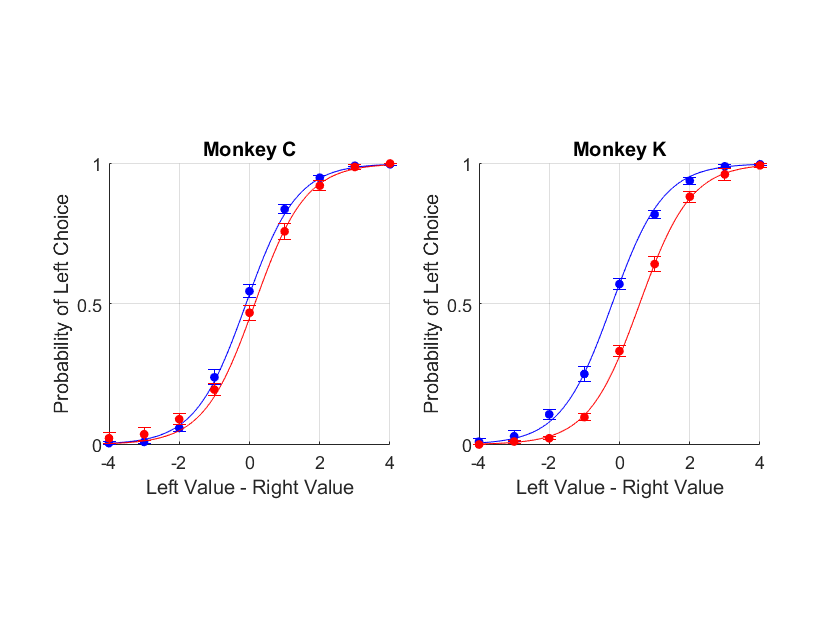

lastFixChoice = grpstats(gazeBias(~sing,:),{'session','vDiff','monk','lastFixIsLeft'},{'mean'},...
    'DataVars','chosen');
lastFixChoice2 = grpstats(lastFixChoice,{'vDiff','monk','lastFixIsLeft'},{'mean','sem'},...
    'DataVars',{'mean_chosen'});


% get variables for gaze biases
monkeys = {'Monkey C','Monkey K'};
% final fixation bias
xPredlastFix_left = gazeBias(1:162,:);
xPredlastFix_left.vDiff = x;
xPredlastFix_left.lastFixIsLeft = logical(ones(162,1));
xPredlastFix_left.monk(82:end) = "MonkeyK";
xPredlastFix_right = gazeBias(1:162,:);
xPredlastFix_right.vDiff = x;
xPredlastFix_right.monk(82:end) = "MonkeyK";
xPredlastFix_right.lastFixIsLeft = logical(zeros(162,1));
lastFixYhat_left = predict(lastFix,xPredlastFix_left);
lastFixYhat_right = predict(lastFix,xPredlastFix_right);


%% plot final fixation bias
clf
for monk = 1:2
    % choice curve
    subplot(1,2,monk)
    
    
    errorbar(-4:4,lastFixChoice2(lastFixChoice2.monk == monks{monk} & lastFixChoice2.lastFixIsLeft,:).mean_mean_chosen, ...
        lastFixChoice2(lastFixChoice2.monk == monks{monk} & lastFixChoice2.lastFixIsLeft,:).sem_mean_chosen,'Color','b',...
        'LineStyle','None','Marker',".","MarkerSize",15); hold on
    plot(xChoice,lastFixYhat_left(idx(monk,:)),'color','b')
    
    
    errorbar(-4:4,lastFixChoice2(lastFixChoice2.monk == monks{monk} & lastFixChoice2.lastFixIsLeft == 0,:).mean_mean_chosen, ...
        lastFixChoice2(lastFixChoice2.monk == monks{monk} & lastFixChoice2.lastFixIsLeft == 0,:).sem_mean_chosen,'Color','r',...
        'LineStyle','None','Marker',".","MarkerSize",15); hold on
    plot(xChoice,lastFixYhat_right(idx(monk,:)),'color','r')
   
    xlabel('Left Value - Right Value')
    ylabel('Probability of Left Choice')
    title(monkeys{monk})
    ylim([0 1])
    xlim([-4 4])
    yticks([0 0.5 1])
    set(gca,'XGrid',1,'YGrid',1)
    pbaspect([1 1 1])
    box off
end

## Cumulative Gaze-Time Bias 

### Analysis

#### Standard Probability

% cumulative gaze-time bias: mixed effects model
timeAdv = fitglme(gazeBias(~sing,:),'chosen ~ timeAdv +(1 + timeAdv|monk)','Distribution','Binomial')

timeAdv = Generalized linear mixed-effects model fit by PL

Model information:
    Number of observations           28693
    Fixed effects coefficients           2
    Random effects coefficients          4
    Covariance parameters                3
    Distribution                    Binomial
    Link                            Logit 
    FitMethod                       MPL   

Formula:
    chosen ~ 1 + timeAdv + (1 + timeAdv | monk)

Model fit statistics:
    AIC           BIC           LogLikelihood    Deviance  
    1.2418e+05    1.2422e+05    -62086           1.2417e+05

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE          tStat      DF       pValue        Lower        Upper   
    {'(Intercept)'}        0.022656    0.038077    0.59501    28691       0.55184    -0.051977    0.097289
    {'timeAdv'    }          5.7775     0.27474     21.029    28691    1.9409e-

% run anova on the output of the model
timeAdvAnova = anova(timeAdv)

timeAdvAnova =     ANOVA marginal tests: DFMethod = 'residual'

    Term                   FStat      DF1    DF2      pValue    
    {'(Intercept)'}        0.35404    1      28691       0.55184
    {'timeAdv'    }         442.22    1      28691    1.9409e-97


#### Value-Corrected Choice Probabilities

% cumulative gaze-time bias with corrected probabilities: 
% mixed effects model
timeAdvC = fitglme(gazeBias(~sing,:),'correctProb ~ timeAdv +(1 + timeAdv|monk)','Distribution','Normal')

timeAdvC = Generalized linear mixed-effects model fit by PL

Model information:
    Number of observations           28693
    Fixed effects coefficients           2
    Random effects coefficients          4
    Covariance parameters                4
    Distribution                    Normal
    Link                            Identity
    FitMethod                       MPL   

Formula:
    correctProb ~ 1 + timeAdv + (1 + timeAdv | monk)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    18994    19044    -9491.1          18982   

Fixed effects coefficients (95% CIs):
    Name                   Estimate     SE           tStat     DF       pValue        Lower        Upper   
    {'(Intercept)'}        0.0068439    0.0027552     2.484    28691      0.012997    0.0014436    0.012244
    {'timeAdv'    }          0.48782     0.047009    10.377    28691    3.4925e-25      0.39568

% run anova on the output of the model
timeAdvCAnova = anova(timeAdvC)

timeAdvCAnova =     ANOVA marginal tests: DFMethod = 'residual'

    Term                   FStat     DF1    DF2      pValue    
    {'(Intercept)'}        6.1703    1      28691      0.012997
    {'timeAdv'    }        107.68    1      28691    3.4925e-25


### Plot Results

% for plotting, we remove outliers. 
gazeBias2 = gazeBias(~sing,:);

for m = 1:2
    upperBound{m} = mean([gazeBias2.timeAdv(gazeBias2.monk==monks{m})])+(3*std([gazeBias2.timeAdv(gazeBias2.monk==monks{m})]));
    lowerBound{m} = mean([gazeBias2.timeAdv(gazeBias2.monk==monks{m})])-(3*std([gazeBias2.timeAdv(gazeBias2.monk==monks{m})]));
    outlierIdx{m} = ([gazeBias2.timeAdv(gazeBias2.monk==monks{m})] >= upperBound{m}) | ([gazeBias2.timeAdv(gazeBias2.monk==monks{m})] <= lowerBound{m});
    disp(['# of outlier trials for  ', monks{m}, ': ', num2str(sum(outlierIdx{m})),', ',num2str(mean(outlierIdx{m})*100) '% of trials'])
end

# of outlier trials for  MonkeyC: 154, 1.0025% of trials
# of outlier trials for  MonkeyK: 103, 0.77264% of trials


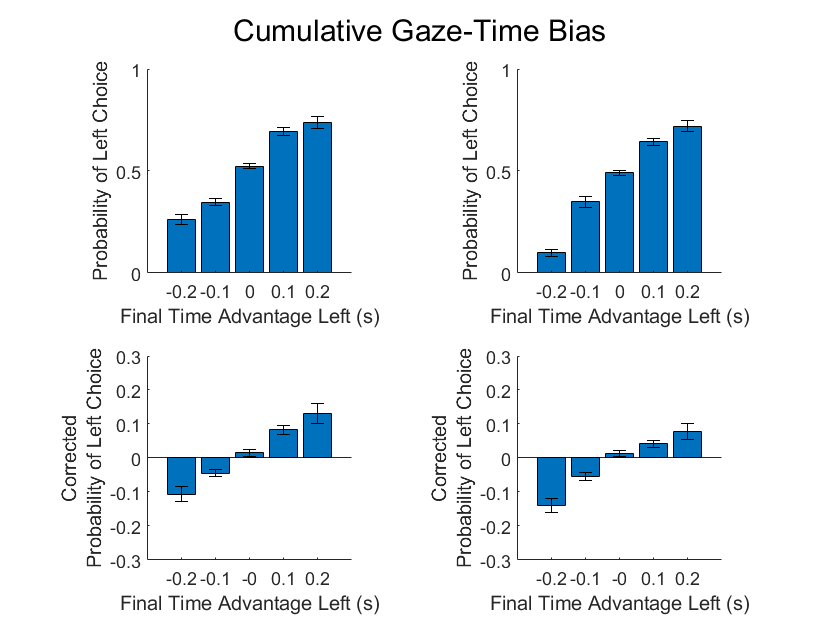

outliers = [outlierIdx{1};outlierIdx{2}];
gazeBias2(outliers,:) = [];
% bin the data for plotting
for mm = 1:2    
    [N{mm},edge{mm}, Id{mm}] = histcounts([gazeBias2.timeAdv(gazeBias2.monk==monks{mm})], 5);
end

Id = [Id{1};Id{2}];
gazeBias2 = addvars(gazeBias2,Id);


clf

for mm = 1:2
   timeAdvChosen = grpstats(gazeBias2,{'session','Id','monk'},{'mean'},...
    'DataVars','chosen');
   timeAdvChosen2 = grpstats(timeAdvChosen,{'Id','monk'},{'mean','sem'},...
    'DataVars','mean_chosen');

   timeAdvChosenC = grpstats(gazeBias2,{'session','Id','monk'},{'mean'},...
    'DataVars','correctProb');
   timeAdvChosenC2 = grpstats(timeAdvChosenC,{'Id','monk'},{'mean','sem'},...
    'DataVars','mean_correctProb');

    [~,centers{mm}] = hist([gazeBias2.timeAdv(gazeBias2.monk==monks{mm})]', 5);
    
    subplot(2,2,mm)
    
    bar(timeAdvChosen2(timeAdvChosen2.monk == monks{mm},:).mean_mean_chosen);hold on
    errorbar(1:5,timeAdvChosen2(timeAdvChosen2.monk == monks{mm},:).mean_mean_chosen, ...
        timeAdvChosen2(timeAdvChosen2.monk == monks{mm},:).sem_mean_chosen,'Color','k',...
        'LineStyle','None','Marker',"none","MarkerSize",15);
   
    
    
    ylabel('Probability of Left Choice')
    box off
    xticklabels([-0.2 -0.1 0 0.1 0.2])
    ylim([0 1])
    yticks([0 0.5 1])
    ylabel('Probability of Left Choice')
    xlabel('Final Time Advantage Left (s)')
    pbaspect([1 1 1])
    
    subplot(2,2,mm+2)
    bar(timeAdvChosenC2(timeAdvChosenC2.monk == monks{mm},:).mean_mean_correctProb);hold on
    errorbar(1:5,timeAdvChosenC2(timeAdvChosenC2.monk == monks{mm},:).mean_mean_correctProb, ...
        timeAdvChosenC2(timeAdvChosenC2.monk == monks{mm},:).sem_mean_correctProb,'Color','k',...
        'LineStyle','none','Marker',"none");
    xticklabels(round(centers{mm},1))
    xlabel('Final Time Advantage Left (s)')
    ylim([-0.3 0.3])
    yticks([-0.3:0.1:0.3])
    ylabel({'Corrected';'Probability of Left Choice'})
    box off
    pbaspect([1 1 1])
    
    sgtitle('Cumulative Gaze-Time Bias')
end